Compute in $\mathbb R^3$ $V \cap W$ where we know their bases

V=sym([1 0; 0 2; 1 -1]);
W=sym([2 0; 2 0; 1 1]);
A=[B1 B2];
N=null(A);
x=V*N(1:2)

$$x = \left(\begin{array}{c} -2\\ -2\\ -1 \end{array}\right)$$

x=-W*N(3:4)

$$x = \left(\begin{array}{c} -2\\ -2\\ -1 \end{array}\right)$$

Lab: intersection between planes


$$\pi_1=-2x+y+2z=0$$



$$\pi_2=-x+y=0$$


syms x y z real;
Eq1=-2*x+y+2*z == 0;
Eq2=-x+y == 0;
S=solve(Eq1,Eq2,'ReturnConditions',true);
B=[S.x;S.y;z]/z

$$B = \left(\begin{array}{c} 2\\ 2\\ 1 \end{array}\right)$$

Case 1: simplest way to solve the system

n1=sym([-2 1 2]');
n2=sym([-1 1 0]');
A=[n1 n2];
null(A')

$$ans = \left(\begin{array}{c} 2\\ 2\\ 1 \end{array}\right)$$

Lab: is a plane and a surface complementary space??

V=[-5 3 0; 2 0 1]';
disp(rank(V));
u=[1 -2 1]';
A=[V u];
disp(rank(A))

Lab: compute the orthogonality of V and its dimension

A=[1 0 1; 0 2 -1]';
disp(rank(A)); % dim V = 2

     2



Vperp=null(A'); % dim Vperp = R^3 - dim V = 1
disp(Vperp' * A); %Verify orthogonality

     0     0



RA=orth(A); disp(Vperp'*RA) %Compute R(A) and verify that it is orthogonal to N(A)

   1.0e-15 *

    0.1110         0



disp(rank([A RA]))  % RA is equal to the Column Space of A

     2



Lab: compute the cartesian equation of V

The plane $\pi$is given by a basis V

A=sym([1 0 1; 0 2 -1]'); %A is the matrix given from the span coefficients of V
n=null(A'); %Compute the normal vector

%Remove denominator:
[num,den]=numden(n);
mult=lcm(den);
n=mult*n;
%---

syms x y z real;
Eqn=[string([x y z]*n) ' = 0']

Lab: display the plane with the observer in front of it

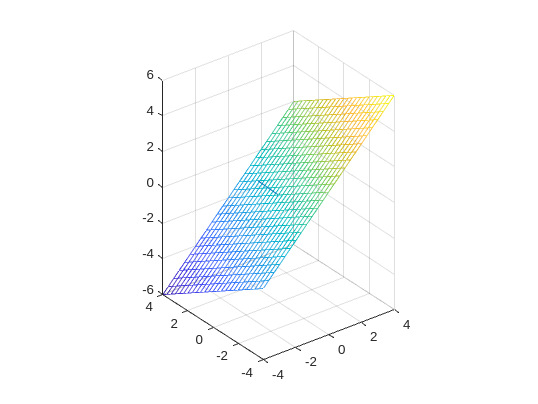

A=sym([1 0 1; 0 2 -1]'); n=null(A');
[x,y]=meshgrid(linspace(-4,4,25));
z=-(n(1)*x+n(2)*y)/n(3);
mesh(x,y,z);
hidden off; hold on; axis equal;
quiver3(0,0,0,n(1),n(2),n(3));

%view([n(1),n(2),n(3)])
[AZ,EL,rho]=cart2sph(n(1),n(2),n(3));
%view(90+AZ*180/pi,EL*180/pi);

## SC_04c

Lab: Compute the 4 fundamental subspaces of A

A=sym([1 2 3; 4 7 5]');
NA=null(A);
NAT=null(A');
RA=colspace(A);
RAT=colspace(A');

disp(NA) % Empty sym
disp(NAT);

$$\left(\begin{array}{c} 11\\ -7\\ 1 \end{array}\right)$$

disp(RA)

$$\left(\begin{array}{cc} 1 & 0\\ 0 & 1\\ -11 & 7 \end{array}\right)$$

disp(RAT)

$$\left(\begin{array}{cc} 1 & 0\\ 0 & 1 \end{array}\right)$$


disp(rank(A));

     2



disp(double(rank([RA A])))

     2



disp(RA'*NAT) %Verify orthogonality

$$\left(\begin{array}{c} 0\\ 0 \end{array}\right)$$

Lab: Gauss Jordan Elimination and subspaces

A=sym([1 0 2 0; 0 2 2 0; 1 -1 1 1]);
S=rref(A); %row reduched echelon form
RAT=colspace(A')

$$RAT = \left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & 1 & 0\\ 2 & 1 & 0\\ 0 & 0 & 1 \end{array}\right)$$

RST=colspace(S')

$$RST = \left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & 1 & 0\\ 2 & 1 & 0\\ 0 & 0 & 1 \end{array}\right)$$

RA=colspace(A)

$$RA = \left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & 1 & 0\\ 0 & 0 & 1 \end{array}\right)$$

RS=colspace(S)

$$RS = \left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & 1 & 0\\ 0 & 0 & 1 \end{array}\right)$$

rank(RA)

ans = 3

rank(RS)

ans = 3

Example: compute the components of a vector along the directions of V and long his orthogonal complement

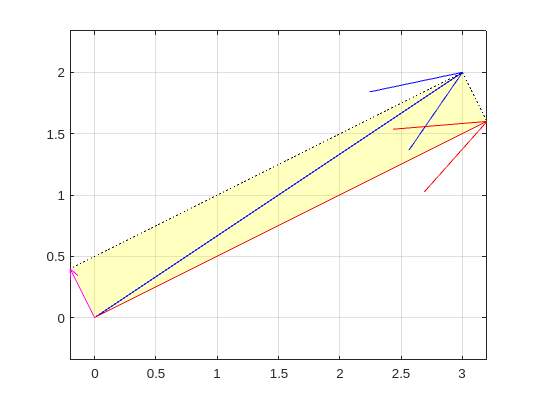

u=[3 2]'; V=[2 1]';
W=null(V'); A=[V W]; c=A\u;
uV=c(1)*V; uW=c(2)*W;
P=[zeros(2,1) uV u uW];
figure; h=patch(P(1,:), P(2,:), 'y');
set(h,'LineStyle',':','FaceAlpha',0.25);
axis equal; grid on; hold on; box on;
h=compass(complex(u(1),u(2)),'b');
h=compass(complex(uV(1),uV(2)), 'r');
h=compass(complex(uW(1),uW(2)), 'm');

Example: Compute the angle between the planes

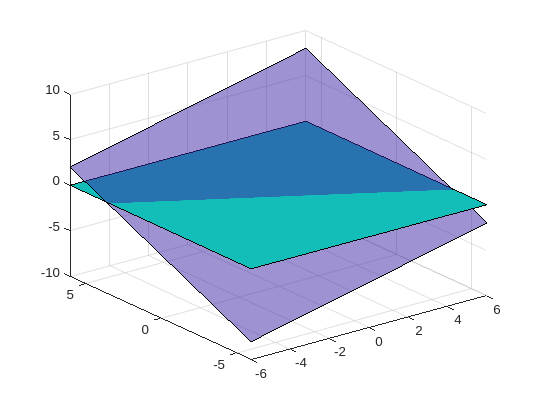

clf;
[x,y]=meshgrid([-6 6]);
z1=(3*x+5*y)/6;
z2=zeros(size(x)); h=surf(x,y,z1); set(h,'FaceAlpha',0.5); hold on; h=surf(x,y,z2);


n1=[3 5 -6]';
n2=[0 0 1]';
cosTH=dot(n1,n2)/(norm(n1)*norm(n2));
TH=acos(abs(cosTH))*180/pi;
disp([TH subspace(n1,n2)*180/pi]);

   44.1814   44.1814

